# Simulación de Sistemas Eléctricos

# Actividad 11: Modelo de predicción con multiples Var. y Filtros

- **Variables independientes (x1,....,xn): Energía, Voltaje......,etc. en t=t0 (Valor actual)**

- **Variable dependiente (f(x)): Energía en t=to+dt (Valor siguiente); dt=1seg**

- **Frecuencia de muestreo de los datos: 1 muestra por segundo (sps)**

- **Venta temporal de predicción: (dt=1día)**

Nombres:

- Estudiante 1: VA

- Estudiante 2: VA

Contenido:

- Descargar datos (.csv) desde desde repositorio (DataPort)

- **Paper: **[https://doi.org/10.1016/j.procs.2022.07.035](https://doi.org/10.1016/j.procs.2022.07.035)

- **Dataset:** [https://ieee-dataport.org/open-access/data-server-energy-consumption-dataset](https://ieee-dataport.org/open-access/data-server-energy-consumption-dataset)

- **Codigo Matlab:** [https://github.com/vasanza/EnergyConsumptionPrediction](https://github.com/vasanza/EnergyConsumptionPrediction)

- **Funciones de Matlab:** [https://github.com/vasanza/Matlab_Code](https://github.com/vasanza/Matlab_Code)

# Preprocesamiento

- **1.- Leer el archivo .csv usando Matlab y graficar los datos**

- **2.- Filtrar los datos (tiempo**, frecuencia, entropia, tiempo-frecuencia, etc.**)**

# Extracción de características

- **3.- Cambiar la frecuencia de muestreo de los datos (1 muestra por Dia)**

- **4.- Adecuar el dataset con la var. independientes o caracteristicas (x1,...,xn) y la var. dependiente f(x)**

# Selección de características

- **5.- Usar la matriz de correlación para eliminar del dataset var. redundantes **

# Modelo de predicción

- **6.- Dataset de training (70%) y testing (30%)**

- **7.- ToolBox de Matlab - Regression Learner (24 algoritmos)**

- **8.- Seleccionar el modelo que tiene un menor error de predicción**

- **9.- Exportar la función del mejor modelo**

- **10.- Calcular el error de predicción usando el dataset de testing**

- **Nota: realizar la prediccion en horas y dias <-------------------------------------- Tarea 1**

- **(*) Despues:**   

-     Invrementar las características temporales

#### **Eliminar datos de memoria y command window**

clear; %Borrar el korspace
clc; %Borrar el command window

#### Configuración de carpeta /src para librerias

%nombre de la carpeta donde estan los codigos
addpath(genpath('./src'));

**Configuranción de carpeta de /data para datasets**

%Nombre de la carpeta donde estan los archvios csv
datapath=fullfile('./data/');
filenames=FindCSV(datapath);

# **1.- Leer el archivo .csv usando Matlab y graficar los datos**

%Esto es lo que se hace con datos .csv
data=readtable(fullfile(datapath,filenames(1).name));
%clear dataRaw; %Borrar de memoria la variable que no usare despues
%Seleccionar las variables electricas de interes
data2=table2array(data(:,1:6)); % Convertir datos de string a float o int
data2(isnan(data2))=0; % Eliminar los datos NaN


#### Graficar todas las Variables

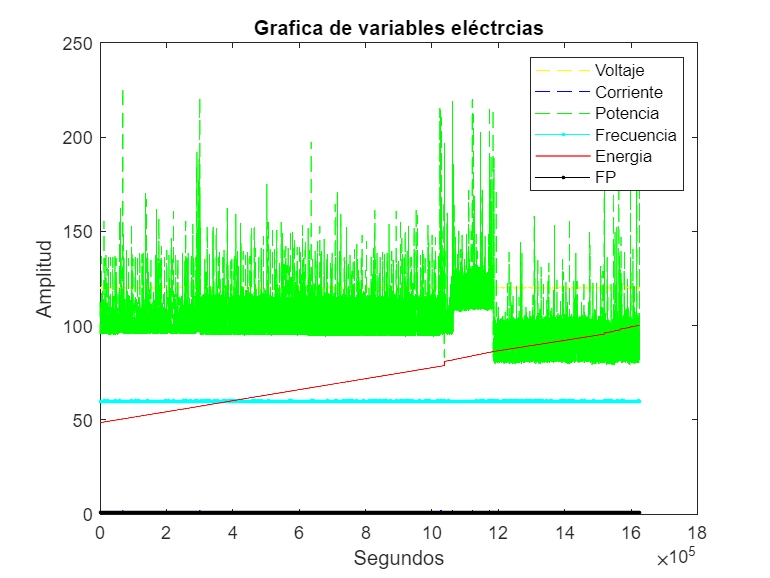

Voltaje=data2(:,1);
Corriente=data2(:,2);
Potencia=data2(:,3);%Columpa de potencia raw
Frecuencia=data2(:,4);
Energia=data2(:,5);
FP=data2(:,6);

figure %crear una nueva grafica
%plot(data2) %plotea la grafica 1
plot(Voltaje,'y--',LineWidth=0.1);
hold on %habilita plotear mas de una grafica en la misma figura
plot(Corriente,'b--',LineWidth=0.1);
plot(Potencia,'g--',LineWidth=0.01);
plot(Frecuencia,'c.-',LineWidth=0.1);
plot(Energia,'r',LineWidth=0.7);
plot(FP,'k.-',LineWidth=0.1);
hold off

title('Grafica de variables eléctrcias');
xlabel('Segundos');
ylabel('Amplitud');
legend('Voltaje','Corriente','Potencia','Frecuencia','Energia','FP');

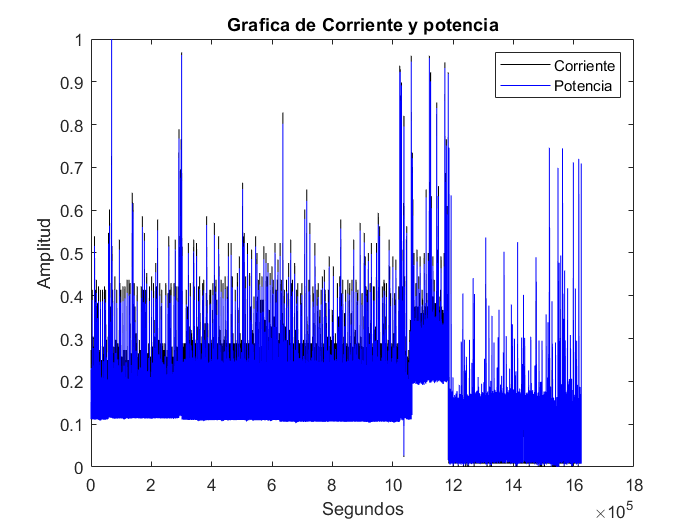

%Grafica de los datos normalizados
[DataNorm] = fNormalization(data2);

figure %crear una nueva grafica
plot(DataNorm(:,2),'k',LineWidth=0.1);
hold on %habilita plotear mas de una grafica en la misma figura
plot(DataNorm(:,3),'b',LineWidth=0.1);
hold off

title('Grafica de Corriente y potencia');
xlabel('Segundos');
ylabel('Amplitud');
legend('Corriente','Potencia');

%Limpiar del workspace variables no utilizadas
clear data;

# **2.- Filtrar los datos**

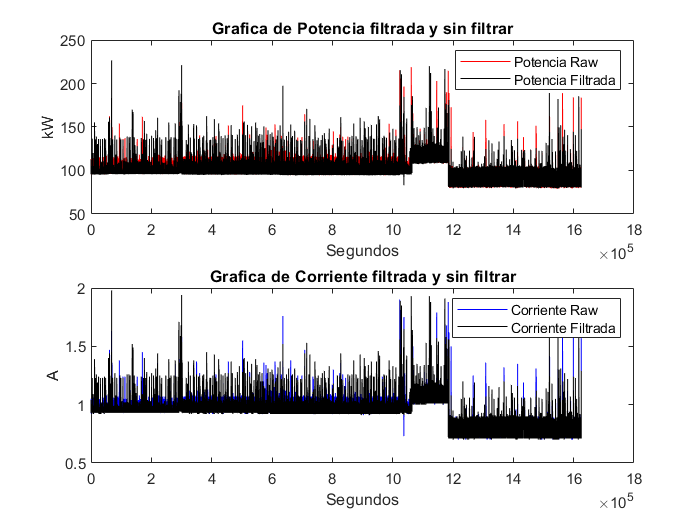

%Corriente
fCorriente=hampel(Corriente);
data2(:,2)=fCorriente;%<-------------------------------------------------
%Potencia
fPotencia=hampel(Potencia);
data2(:,3)=fPotencia;%sobrescribir la potencia raw por la filtrada<------


figure %crear una nueva grafica
subplot(2,1,1);
plot(Potencia(:,1),'r',LineWidth=0.01);
hold on %habilita plotear mas de una grafica en la misma figura
plot(data2(:,3),'k',LineWidth=0.1);
hold off
title('Grafica de Potencia filtrada y sin filtrar');
xlabel('Segundos');
ylabel('kW');
legend('Potencia Raw','Potencia Filtrada');

subplot(2,1,2);
plot(Corriente(:,1),'b',LineWidth=0.01);
hold on %habilita plotear mas de una grafica en la misma figura
plot(data2(:,2),'k',LineWidth=0.1);
hold off
title('Grafica de Corriente filtrada y sin filtrar');
xlabel('Segundos');
ylabel('A');
legend('Corriente Raw','Corriente Filtrada');

# **3.- Cambiar la frecuencia de muestreo de los datos (1 muestra por Días)**

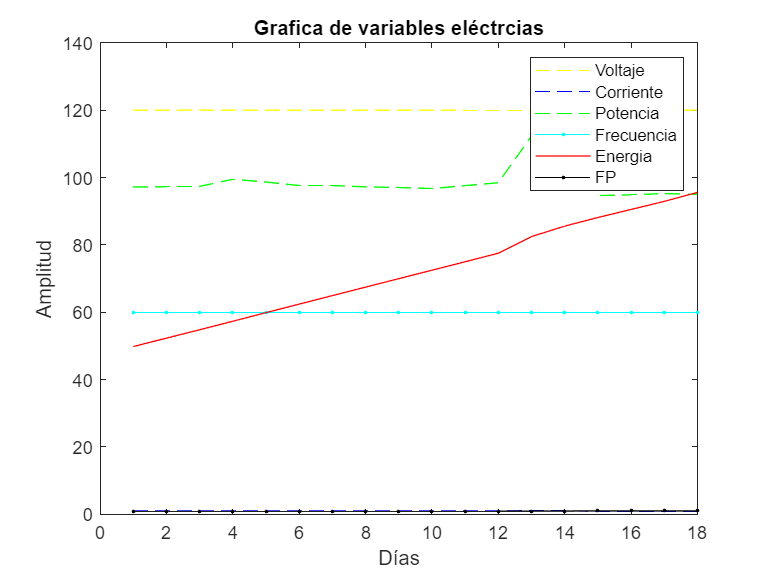

win=3600*24; %dado a que los datos estan en segundos y queremos llevarlo a Días
data2Mean=fData_MeanWin(data2,win);%3600*24 segundos 
data2Max=fData_MaxWin(data2,win);%3600*24 segundos
data2Min=fData_MinWin(data2,win);%3600*24 segundos
data2Std=fData_StdWin(data2,win);%3600*24 segundos<---------------------- Tarea
data2Median=fData_MedianWin(data2,win);%3600*24 segundos<---------------------- Tarea

figure %crear una nueva grafica
plot(data2Mean(:,1),'y--',LineWidth=0.1);
hold on %habilita plotear mas de una grafica en la misma figura
plot(data2Mean(:,2),'b--',LineWidth=0.1);
plot(data2Mean(:,3),'g--',LineWidth=0.01);
plot(data2Mean(:,4),'c.-',LineWidth=0.1);
plot(data2Mean(:,5),'r',LineWidth=0.7);
plot(data2Mean(:,6),'k.-',LineWidth=0.1);
hold off


title('Grafica de variables eléctrcias');
xlabel('Días');
ylabel('Amplitud');
legend('Voltaje','Corriente','Potencia','Frecuencia','Energia','FP');

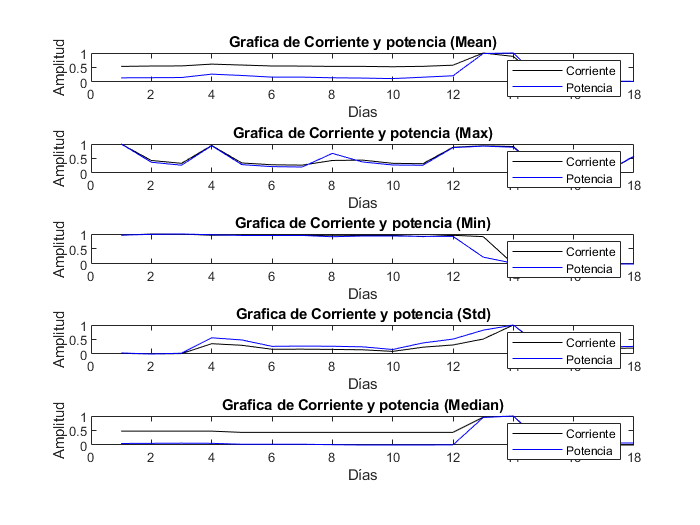

%Grafica de los datos normalizados
[DataNorm2] = fNormalization(data2Mean);
[DataNorm3] = fNormalization(data2Max);
[DataNorm4] = fNormalization(data2Min);
[DataNorm5] = fNormalization(data2Std);%<-----------------Tarea
[DataNorm6] = fNormalization(data2Median);%<-----------------Tarea

figure %crear una nueva grafica
subplot(5,1,1);
plot(DataNorm2(:,2),'k',LineWidth=0.1);
hold on %habilita plotear mas de una grafica en la misma figura
plot(DataNorm2(:,3),'b',LineWidth=0.1);
hold off
title('Grafica de Corriente y potencia (Mean)');
xlabel('Días');
ylabel('Amplitud');
legend('Corriente','Potencia');
subplot(5,1,2);
plot(DataNorm3(:,2),'k',LineWidth=0.1);
hold on %habilita plotear mas de una grafica en la misma figura
plot(DataNorm3(:,3),'b',LineWidth=0.1);
hold off
title('Grafica de Corriente y potencia (Max)');
xlabel('Días');
ylabel('Amplitud');
legend('Corriente','Potencia');
subplot(5,1,3);
plot(DataNorm4(:,2),'k',LineWidth=0.1);
hold on %habilita plotear mas de una grafica en la misma figura
plot(DataNorm4(:,3),'b',LineWidth=0.1);
hold off
title('Grafica de Corriente y potencia (Min)');
xlabel('Días');
ylabel('Amplitud');
legend('Corriente','Potencia');
subplot(5,1,4);
plot(DataNorm5(:,2),'k',LineWidth=0.1);
hold on %habilita plotear mas de una grafica en la misma figura
plot(DataNorm5(:,3),'b',LineWidth=0.1);
hold off
title('Grafica de Corriente y potencia (Std)');
xlabel('Días');
ylabel('Amplitud');
legend('Corriente','Potencia');
subplot(5,1,5);
plot(DataNorm6(:,2),'k',LineWidth=0.1);
hold on %habilita plotear mas de una grafica en la misma figura
plot(DataNorm6(:,3),'b',LineWidth=0.1);
hold off
title('Grafica de Corriente y potencia (Median)');
xlabel('Días');
ylabel('Amplitud');
legend('Corriente','Potencia');

%Limpiar del workspace variables no utilizadas
clear data2; clear FP; clear Potencia; clear Frecuencia; clear Energia;
 clear Corriente;clear Voltaje;clear win;

# **4.- Adecuador el dataset con la var. independientes (x1,...,xn) y la var. dependiente f(x)**

**Variables independientes (x1,....,xn): Energía, Voltaje......,etc. en t=t0 (Valor actual)**

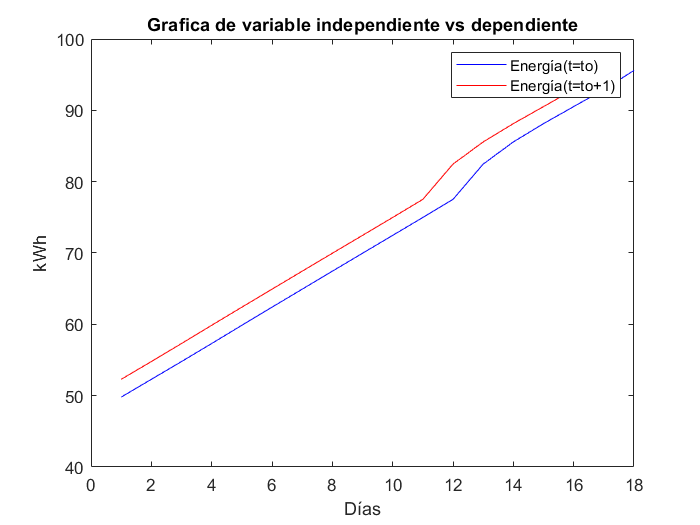

% Voltaje=data2Mean(:,1);
% Corriente=data2Mean(:,2);
% Potencia=data2Mean(:,3);
% Frecuencia=data2Mean(:,4);
 Energia=data2Mean(:,5);
% FP=data2Mean(:,6);
 
 % Variables independientes (x1,....,xn) en tiempo t=t0
% input=[Voltaje(1:size(Voltaje,1)-1,1) Corriente(1:size(Corriente,1)-1,1)...
%     Potencia(1:size(Potencia,1)-1,1) Frecuencia(1:size(Frecuencia,1)-1,1)...
%     Energia(1:size(Energia,1)-1,1) FP(1:size(FP,1)-1,1)];

input=[data2Mean(1:size(data2Mean,1)-1,:) data2Max(1:size(data2Max,1)-1,:)...
    data2Min(1:size(data2Min,1)-1,:) data2Std(1:size(data2Std,1)-1,:)...
    data2Median(1:size(data2Median,1)-1,:)];
% Variable dependient f(x) en el tiempo t=t0+dt (1 día)
output=Energia(2:size(Energia,1),1);

%Primeras columnas son las entradas o varianles independientes
%La ultima columna es la salida o variable dependiente
dataset=[input output];

 figure %crear una nueva grafica
 plot(Energia(:,1),'b',LineWidth=0.1);
 hold on %habilita plotear mas de una grafica en la misma figura
 plot(output(:,1),'r',LineWidth=0.1);
 hold off
% 
 title('Grafica de variable independiente vs dependiente');
 xlabel('Días');
 ylabel('kWh');
 legend('Energía(t=to)','Energía(t=to+1)');

 %Limpiar del workspace variables no utilizadas
clear FP; clear Potencia; clear Frecuencia; clear Energia;
clear Corriente;clear Voltaje; clear data2Mean;
clear input; clear output;

# **5.- Usar la matriz de correlación para eliminar del dataset var. redundantes **

threshold=0.80;%<---------------------------------------------------------
DataFeatures=dataset(:,1:size(dataset,2)-1);%no incluir la variable de salida
FeaturesLabels={'Vmean','Cmean','Pmean','Fmean','Emean','FPmean'...
    'Vmax','Cmax','Pmax','Fmax','Emax','FPmax'...
    'Vmin','Cmin','Pmin','Fmin','Emin','FPmin'...
    'Vstd','Cstd','Pstd','Fstd','Estd','FPstd'...
    'Vmedian','Cmedian','Pmedian','Fmedian','Emedian','FPmedian'};
corr_matr = corrcoef(DataFeatures)

corr_matr =     1.0000   -0.7862   -0.9664   -0.2751   -0.1847    0.0619    0.0430   -0.6120   -0.5861   -0.0000   -0.1906   -0.2409    0.6039   -0.0179    0.2300   -0.0162   -0.1553    0.0979   -0.9030   -0.8340   -0.8676    0.3605   -0.9418   -0.8561    0.8677   -0.8649   -0.8950       NaN   -0.1852    0.0616
   -0.7862    1.0000    0.7624    0.3268   -0.3807   -0.6359   -0.5869    0.7613    0.7176    0.0000   -0.3752   -0.0750   -0.6047    0.5757    0.3732   -0.0923   -0.4075    0.0024    0.7288    0.4754    0.5477   -0.4312    0.7764    0.6649   -0.7462    0.9692    0.5749       NaN   -0.3804   -0.6302
   -0.9664    0.7624    1.0000    0.2287    0.1919    0.0144    0.0435    0.6399    0.6119   -0.0000    0.1979    0.1471   -0.6212   -0.0623   -0.3127    0.1058    0.1618    0.0254    0.9139    0.8461    0.8457   -0.3309    0.9633    0.7911   -0.8720    0.8724    0.9609       NaN    0.1924    0.0194
   -0.2751    0.3268    0.2287    1.0000   -0.3045   -0.2414   -0.2704    0.4334    0

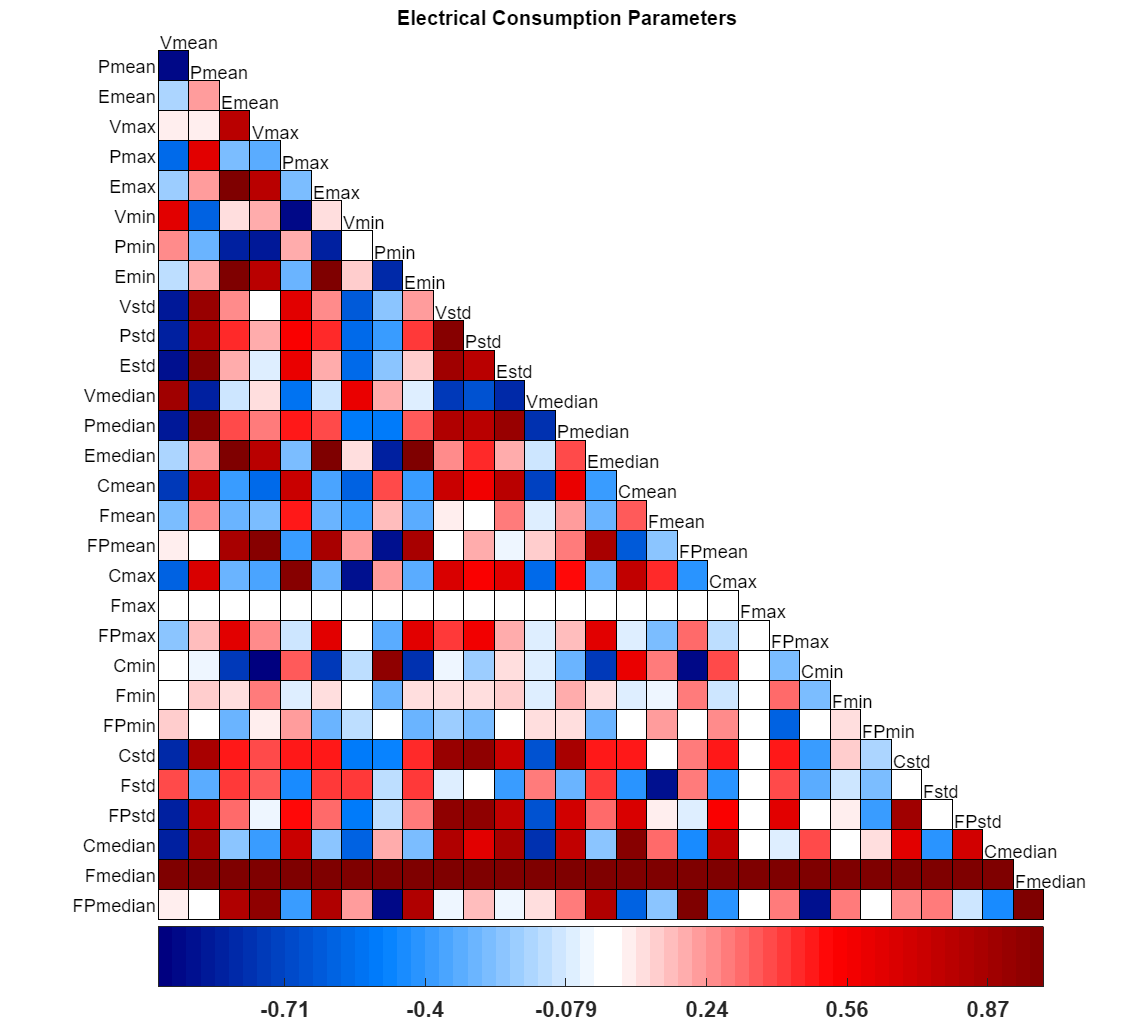

NewDataFeatures =   120.0333    0.9401   97.2000   59.9686   49.7992    1.9800   60.1000    0.9600  119.4000    0.9200   59.8000    0.8400    0.0476   60.0000
  120.0346    0.9431   97.2813   59.9678   52.2916    1.5200   60.1000    0.9400  119.7000    0.9300   59.7000    0.7900    0.0481   60.0000
  120.0415    0.9440   97.3907   59.9657   54.7841    1.4400   60.1000    0.9600  119.7000    0.9300   59.8000    0.8400    0.0490   60.0000
  120.0240    0.9581   99.4929   59.9665   57.3107    1.9400   60.1000    1.0000  119.4000    0.9200   59.8000    0.7700    0.0489   60.0000
  120.0179    0.9509   98.6712   59.9664   59.8672    1.4500   60.1000    1.0000  119.7000    0.9200   59.8000    0.7600    0.0489   60.0000
  120.0242    0.9434   97.6289   59.9672   62.4058    1.4000   60.1000    1.0000  119.7000    0.9200   59.8000    0.7300    0.0485   60.0000
  120.0140    0.9427   97.6373   59.9681   64.9289    1.3900   60.1000    1.0000  119.7000    0.9200   59.8000    0.7800    0.0479   60.

NewFeaturesLabels = 1×14 cell array
    {'Vmean'}    {'Cmean'}    {'Pmean'}    {'Fmean'}    {'Emean'}    {'Cmax'}    {'Fmax'}    {'FPmax'}    {'Vmin'}    {'Cmin'}    {'Fmin'}    {'FPmin'}    {'Fstd'}    {'Fmedian'}


LabelsRemove = 1×16 cell array
    {'FPmean'}    {'Vmax'}    {'Pmax'}    {'Emax'}    {'Pmin'}    {'Emin'}    {'Vstd'}    {'Cstd'}    {'Pstd'}    {'Estd'}    {'FPstd'}    {'Vmedian'}    {'Cmedian'}    {'Pmedian'}    {'Emedian'}    {'FPmedian'}


[NewDataFeatures,NewFeaturesLabels,LabelsRemove] = Feature_Selection(DataFeatures,FeaturesLabels,threshold)

# **6.- Dataset de training (70%) y testing (30%)**

dataset2=[NewDataFeatures dataset(:,size(dataset,2))];
%70 de entrenamiento y 30% de testing
Training=dataset2(1:round(size(dataset2,1)*0.7),:);% fila 1 hasta la fila del 70% de todas las filas
%desde la fila del 70% de todas las filas hasta la ultima fila
Testing=dataset2(round(size(dataset2,1)*0.7)+1:round(size(dataset2,1)),:);

 %Limpiar del workspace variables no utilizadas
clear NewDataFeatures; clear DataFeatures;
clear threshold; clear NewFeaturesLabels; clear LabelsRemove;
clear dataset2; clear FeaturesLabels;

# **7.- ToolBox de Matlab - Regression Learner (24 algoritmos)**

regressionLearner

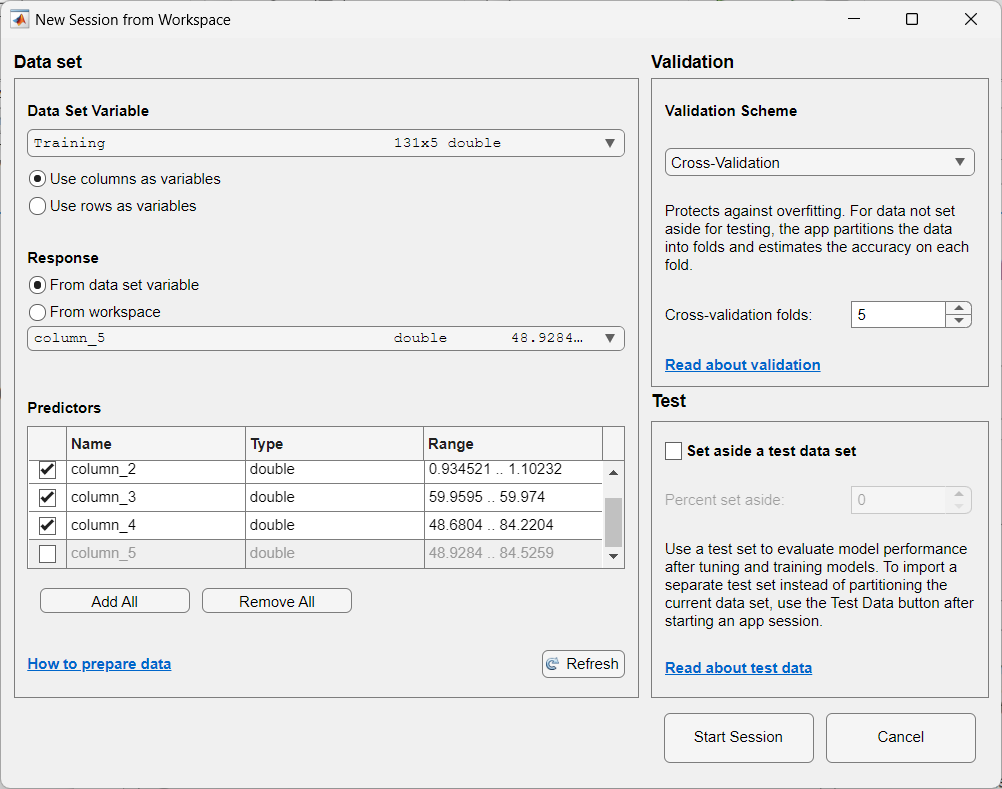

# **8.- Seleccionar el modelo que tiene un menor error de predicción**

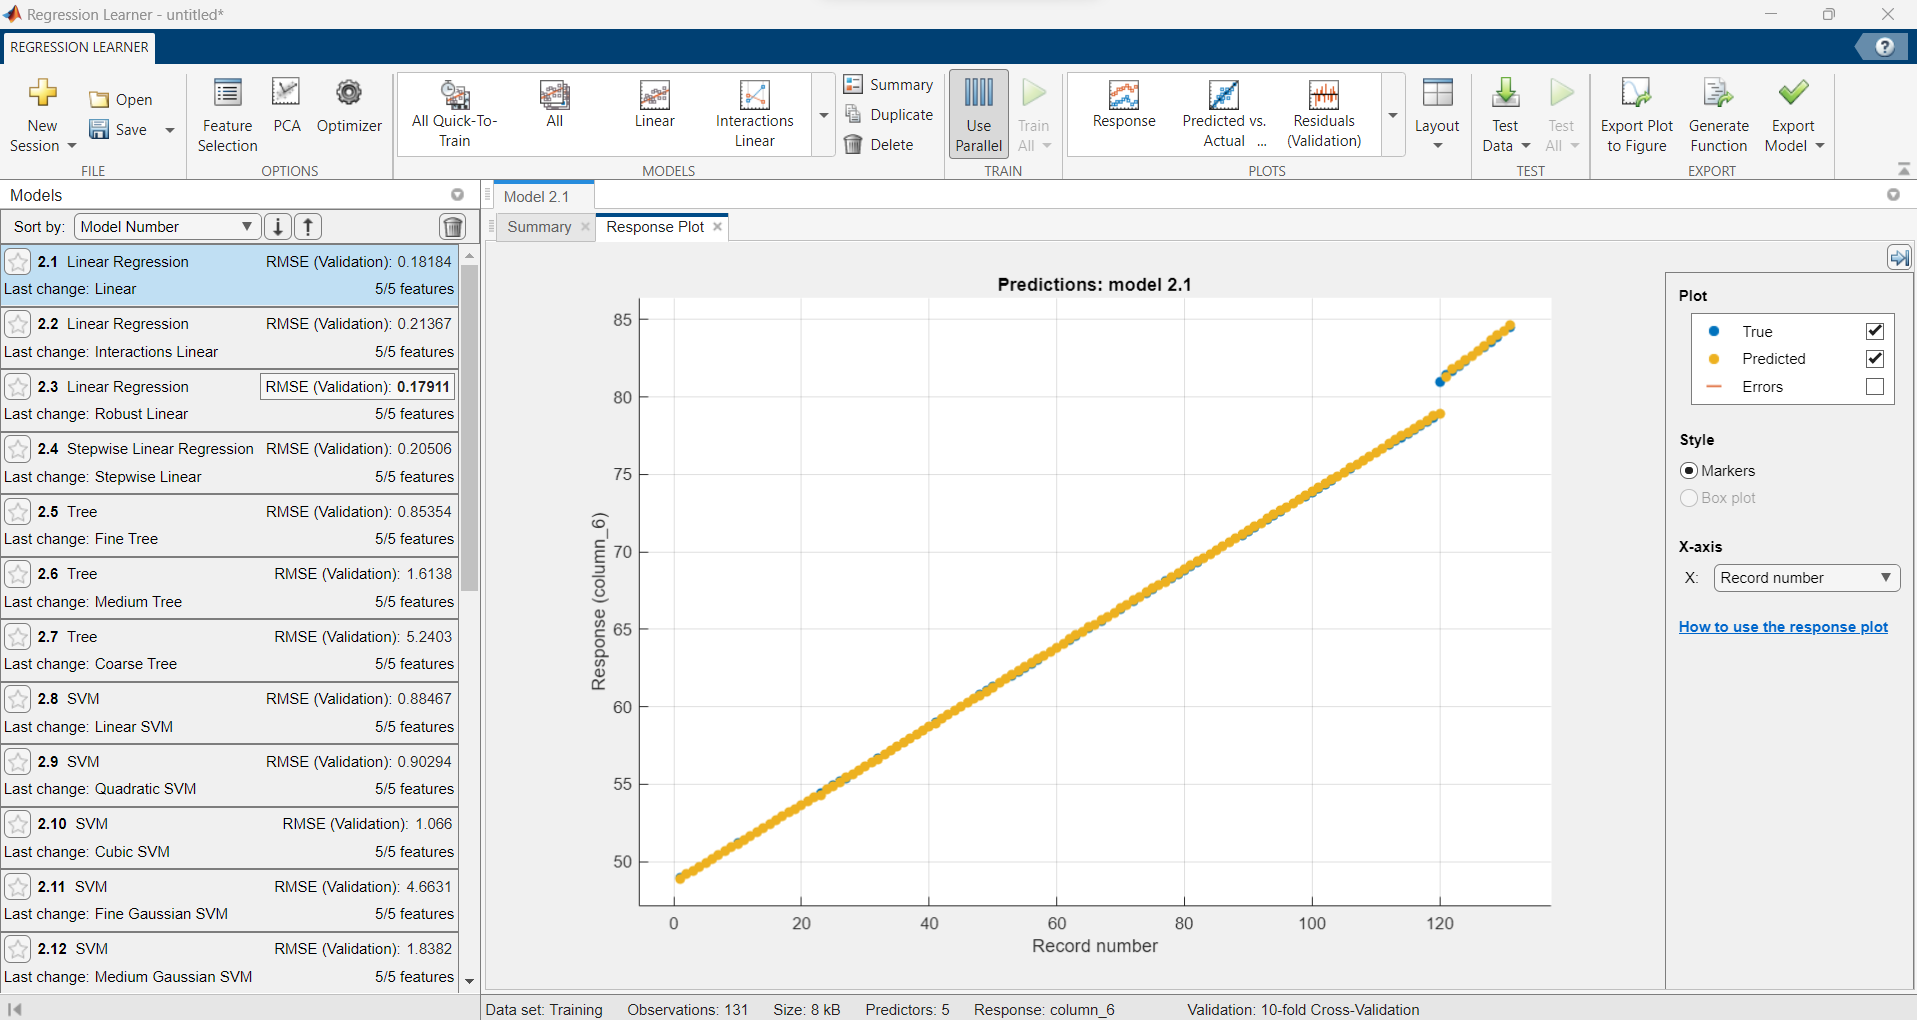

# **9.- Exportar la función del mejor modelo**

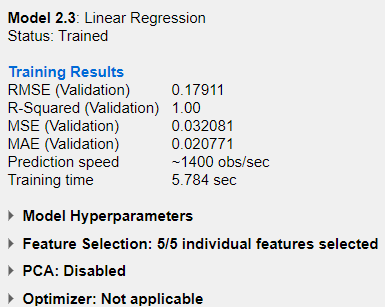

%Gaussian Process Regression
[trainedModel, validationRMSE] = trainRegressionModel_dias(Training)

trainedModel = struct with fields:
      predictFcn: @(x)linearModelPredictFcn(predictorExtractionFcn(x))
     LinearModel: [1×1 LinearModel]
           About: 'This struct is a trained model exported from Regression Learner R2022a.'
    HowToPredict: 'To make predictions on a new predictor column matrix, X, use: ↵  yfit = c.predictFcn(X) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵X must contain exactly 14 columns because this model was trained using 14 predictors. ↵X must contain only predictor columns in exactly the same order and format as your training ↵data. Do not include the response column or any columns you did not import into the app. ↵ ↵For more information, see How to predict using an exported model.'


validationRMSE = 2.2974

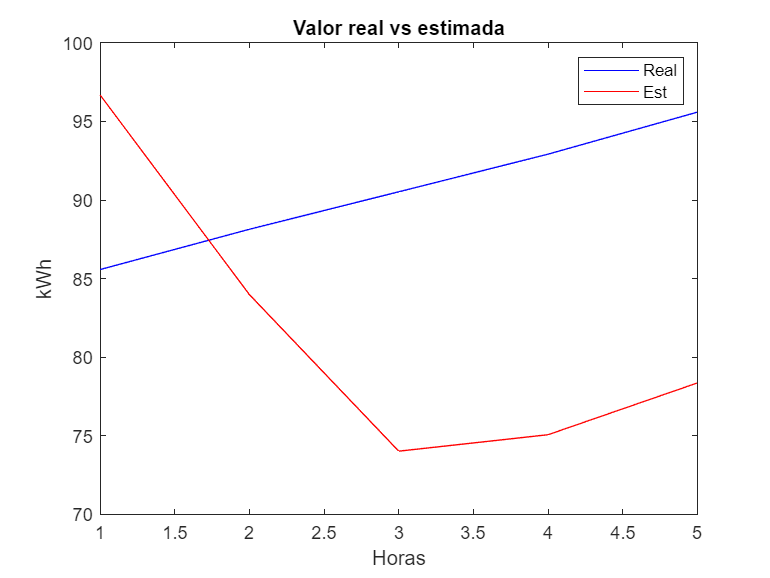

%[trainedModel, validationRMSE] = trainRegressionModel_fLR(Training)
%Aqui le datos al modelo solo las varibles de entrada
EnergiaEst=trainedModel.predictFcn(Testing(:,1:size(Testing,2)-1));%Sin la salida ya que el modelo lo predice
EnergiaReal=Testing(:,size(Testing,2)); %<------------------------ Energía Real

 figure %crear una nueva grafica
 plot(EnergiaReal,'b',LineWidth=0.1);
 hold on %habilita plotear mas de una grafica en la misma figura
 plot(EnergiaEst,'r',LineWidth=0.1);
 hold off
% 
 title('Valor real vs estimada');
 xlabel('Horas');
 ylabel('kWh');
 legend('Real','Est');

# **10.- Calcular el error de predicción usando el dataset de testing**

%[rmse,mse,r2] = fBar_RmseMseR2(EnergiaEst,Testing(:,2))
%r2 = fR2(EnergiaEst,EnergiaReal)
rmse = sqrt(immse(EnergiaEst,EnergiaReal))%0.2103 %0.1126

rmse = 14.3519

mse = immse(EnergiaEst,EnergiaReal)%0.0442 %0.0127

mse = 205.9757

mae = sum(abs(EnergiaEst-EnergiaReal)/length(EnergiaEst))%0.1988 %0.0559

mae = 13.3787

%Error
PorcentajeError1 = rmse*100/max(EnergiaReal)

PorcentajeError1 = 15.0133

%Exactitud
PorcentajeExactitud1=1-PorcentajeError1

PorcentajeExactitud1 = -14.0133

%Error
PorcentajeError2 = rmse*100/mean(EnergiaReal)

PorcentajeError2 = 15.8498

%Exactitud
PorcentajeExactitud2=1-PorcentajeError2

PorcentajeExactitud2 = -14.8498